# Deforestation radius estimation

This code estimates how much the same synapse moves between the two imaging sessions. To do so - 4 fish were imaged with with the same time interval as during the training , same synapses were manually segmented for one cell at time point 1 and the same cell at time point 2. To run this code you will need 8 csv files : coordinates of synapses in tp 1 and tp2, after rigid registration to tp1. The files are assigned to [Dataset: 1-1F8C](https://synapse.isrd.isi.edu/chaise/record/#1/Zebrafish:Cohort/RID=1-1F8C) with the following RIDs: 

- Fish 1: 1-1RWG and 1-1RXM (1-1GGP_tp1.csv, 1-1GGR_tp2_Rigid.csv)

- Fish 2: 1-1RWJ and 1-1RXJ (1-1GGT_tp1.csv, 1-1GGW_tp2_Rigid.csv)

- Fish 3: 1-1RWM and 1-1RXG (1-1GGY_tp1.csv, 1-1GH0_tp2_Rigid.csv)

- Fish 4: 1-1RWP and 1-1RXE (1-1GH2_tp1.csv, 1-1GH4_tp2_Rigid.csv)

For your convenience, they are already in the *deforest_rad\data* folder.

## change folder to : deforest_rad

cd 'D:\Code\repos\synapse-redistribution\deforest_rad'

## load segmented synapses 

%% Rigid 
data_folder = 'data\';

% (i_cell,synapses,data_folder,id_tp1,id_tp2,cell_id,res_tp1,res_tp2)
synapses = load_timepoints(1,[],data_folder,'1-1GGP','1-1GGR','fish_1',[1 1 0.602],[1 1 1]);

resolution = [0.2075665 0.2075665 0.6016173]; % um
synapses = load_timepoints(2,synapses,data_folder,'1-1GGT','1-1GGW','fish_2',[1 1 resolution(3)],[1 1 1]);

synapses = load_timepoints(3,synapses,data_folder,'1-1GGY','1-1GH0','fish_3',[1 1 resolution(3)],resolution);

synapses = load_timepoints(4,synapses,data_folder,'1-1GH2','1-1GH4','fish_4',[1 1 resolution(3)],[1 1 1]);
   

## get distances between synapses

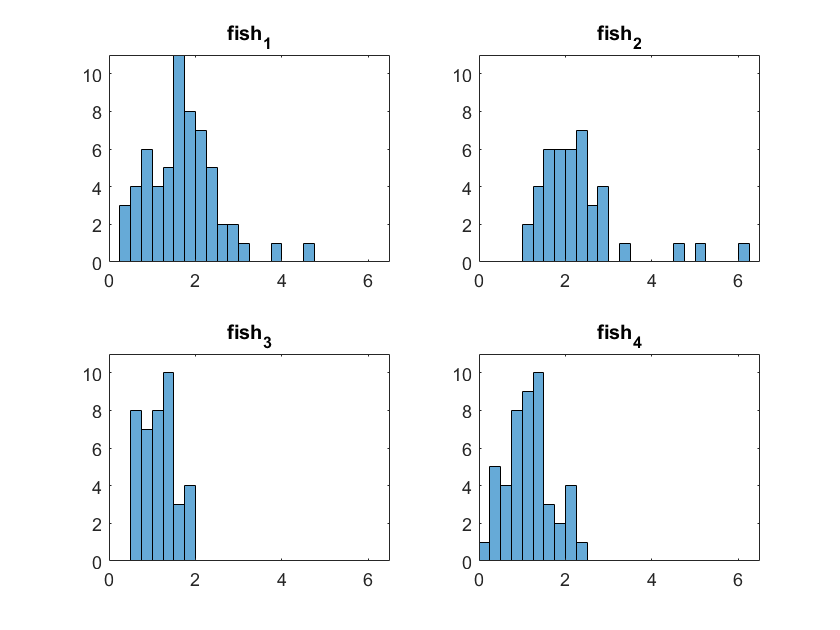

diff_3d = cell(1,4);

figure;
for iFish = 1:4
subplot(2,2,iFish);
diff_3d{iFish} = get_distances(synapses.tp1{iFish},synapses.tp2{iFish});
histogram(diff_3d{iFish},'BinWidth',0.25)
xlim([0 6.5])
ylim([0 11])
title(synapses.id{iFish})

end

## look at synapse shift in 3D

For example , here are the paired synapses for fish 4.

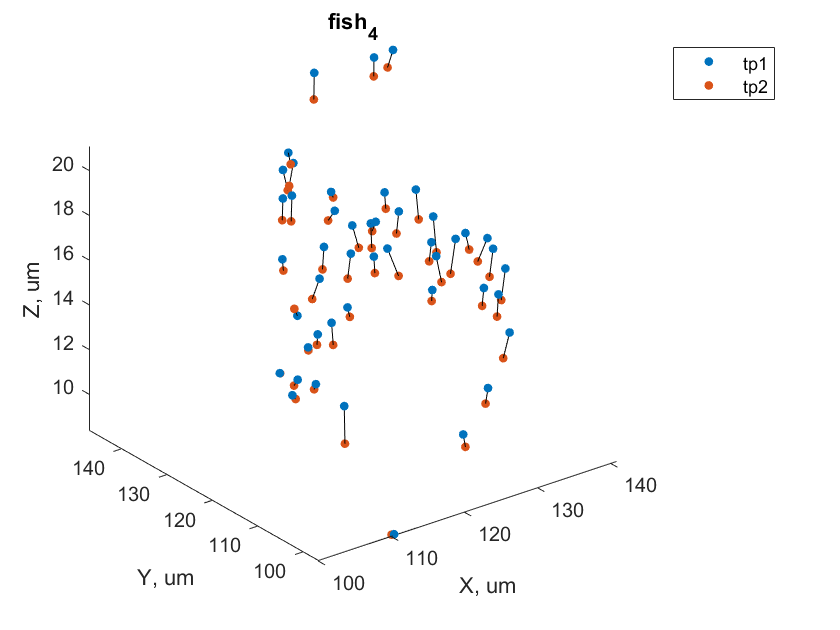

figure;
plot_pairs(diff_3d{iFish},synapses.tp1{iFish},synapses.tp2{iFish},0)
title(synapses.id{iFish})

## save distances as csv

maxPairs = max([length(diff_3d{1}),length(diff_3d{2}),length(diff_3d{3}),length(diff_3d{4})]);
nanArr = nan(maxPairs,4);
nanArr(1:length(diff_3d{1}),1) = diff_3d{1};
nanArr(1:length(diff_3d{2}),2) = diff_3d{2};
nanArr(1:length(diff_3d{3}),3) = diff_3d{3};
nanArr(1:length(diff_3d{4}),4) = diff_3d{4};

t = table(nanArr(:,1),nanArr(:,2),nanArr(:,3),nanArr(:,4));
t.Properties.VariableNames = synapses.id

t = 60×4 table
    fish_1     fish_2    fish_3     fish_4 
    _______    ______    _______    _______

     1.5471    5.0675     1.1879    0.42449
    0.94845    3.2529     1.3918    0.82991
     1.3187    2.3433    0.88485    0.42947
     1.4499     1.853    0.85324     1.0801
     1.7061     2.217    0.67395     1.3463
     1.6852    1.9476     1.5468     1.0101
     2.0719    1.1213     1.2313    0.98249
     2.3159    2.1957     1.2074    0.52724
    0.88489     2.469     1.4674      1.069
    0.40436    2.7777     1.1376     1.2518
    0.88849    1.7496    0.72145     1.2061
     1.1929    1.7418    0.75567      1.656
     1.2555    2.2056     1.3015      1.267
    0.93631    6.0283    0.62898     2.1211
    0.95983    4.6737    0.70645     2.3413
     2.5245    2.5034     1.9185    0.62078


writetable(t,[data_folder,'paiwise_distance.csv']);

## plot distances all together

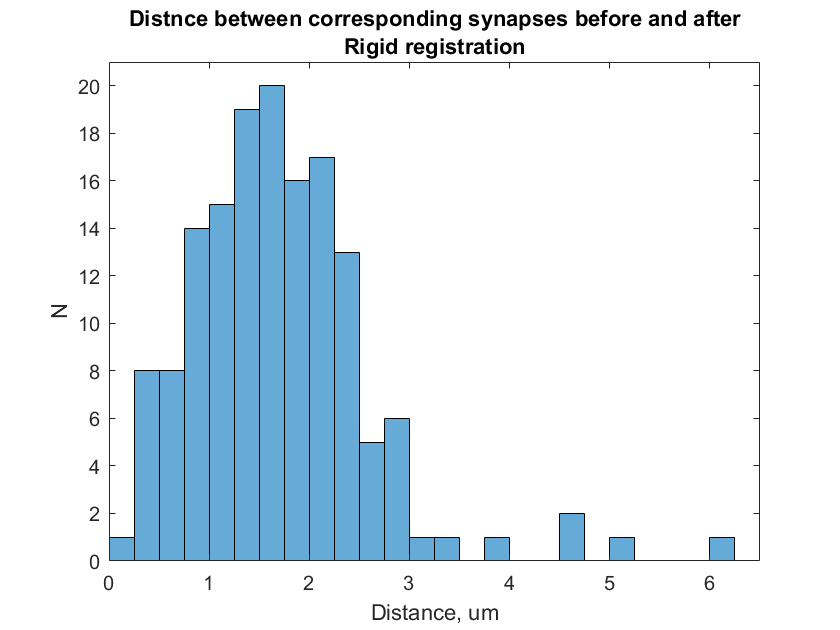

figure
diff_3d = get_distances(cat(1,synapses.tp1{1},synapses.tp1{2},synapses.tp1{4}),cat(1,synapses.tp2{1},synapses.tp2{2},synapses.tp2{4}));
histogram(diff_3d,'BinWidth',0.25)
title({'Distnce between corresponding synapses before and after';'Rigid registration'})
xlabel('Distance, um');
ylim([0 21]);
xlim([0 6.5]);
ylabel('N');

**HELPER FUNCTIONS**

function diff_3d = get_distances(synapses_tp1,synapses_tp2)
diff_tp = synapses_tp1 - synapses_tp2;
diff_3d = sqrt(sum(diff_tp.^ 2,2));
end

function plot_pairs(diff_3d,synapses_tp1,synapses_tp2,thr)
plot3(synapses_tp1(:,1),synapses_tp1(:,2),synapses_tp1(:,3),...
    '.','MarkerSize',15)
hold on
plot3(synapses_tp2(:,1),synapses_tp2(:,2),synapses_tp2(:,3),...
    '.','MarkerSize',15)
xlabel('X, um');
ylabel('Y, um');
zlabel('Z, um');

% show connector only for pairs that are farther away than thr
for i_pair = 1:length(diff_3d)
    if diff_3d(i_pair)>thr
        hold on
        plot3([synapses_tp1(i_pair,1),synapses_tp2(i_pair,1)],...
            [synapses_tp1(i_pair,2),synapses_tp2(i_pair,2)],...
            [synapses_tp1(i_pair,3),synapses_tp2(i_pair,3)],'Color',[0 0 0]);
    end
end
h = findobj(gca,'Type','line');
legend([h(end) h(end-1)],'tp1','tp2');

end

function synapses = load_timepoints(i_cell,synapses,data_folder,id_tp1,id_tp2,cell_id,res_tp1,res_tp2)
% loads coordinates of synapses at tp1 and tp2 and asigns them to the
% provided id

synapses_csv = readtable([data_folder,id_tp1,'_tp1.csv']);
synapses.tp1{i_cell} = [synapses_csv.X synapses_csv.Y synapses_csv.Slice].*res_tp1;

synapses_csv = readtable([data_folder,id_tp2,'_tp2_Rigid.csv']);
% tp2 segmented in different versions : can be Slice or Z 
if ~ismember('Z', synapses_csv.Properties.VariableNames)
    synapses.tp2{i_cell} = [synapses_csv.X synapses_csv.Y synapses_csv.Slice].*res_tp2;
else
    synapses.tp2{i_cell} = [synapses_csv.X synapses_csv.Y synapses_csv.Z].*res_tp2;
end

synapses.id{i_cell} = cell_id;

end
